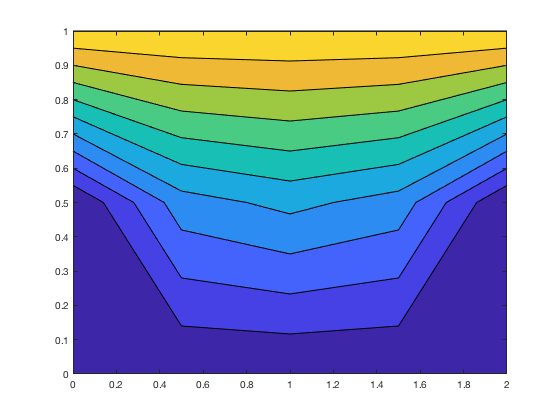

close all
clear all

c=50; %temperature given for sides and bottom
t=150; %temerature given for the top

b=[c;c;c;c;c;c;0;0;0;c;t;t;t;t;t]; %this is the b matrix in AT=b
A=diag(ones(1,15)*-4,0)+diag(ones(1,14),1)+diag(ones(1,14),-1)+diag(ones(1,10),-5)+diag(ones(1,10),5);
%first I defined the center nodes
A(1:6,:)=0; %then I set all non center nodes equal to zero
A(10:15,:)=0; %then I set all non center nodes equal to zero

A(1:6,1:6)=diag(ones(1,6),0); %then I defined the nodes on the bottom and left side middle
A(10:15,10:15)=diag(ones(1,6),0); %then I set all of the nodes on the top, right side and left side top

T=inv(A)*b; %solve for temerature
x=[0:.5:2];y=[0:.5:1]; %x and y intervals

TT=reshape(T,5,3)'; %reshape T to look like the rectangle
TT=flipud(TT); %flip TT so the top is on top and the bottom is on bottom

[XX,YY]=meshgrid(x,y); %meshgrid x and y
YY=flipud(YY); %flip y so the top is on top and the bottom is on bottom
contourf(XX,YY,TT) %contor graph TT for XX by YY